clc
data=load('data1.txt')

data =     1.0000    1.5000    3.0000    5.0000   10.0000   20.0000   45.0000   50.0000   30.0000    2.0000    1.0000    0.5000
    3.5000    3.0000    5.0000    9.0000   11.0000   24.0000   49.0000   50.0000   31.0000    4.0000    4.0000    3.5000
    7.0000    6.0000    8.0000    9.0000   15.0000   25.0000   52.0000   55.0000   37.0000    7.0000    5.0000    6.0000


% Create a plot of the data
xt=(data');
yt=xt(:);
% k pair
% Define the parameters
k = 12;  % value of k
T=length(yt);
m=k/2

m = 6

% Calculate the rolling mean using the formula
rolling_means=zeros(T,1);
for i=k:T-1
    rolling_means(i-1) = ( (0.5*(yt(i-(k-1)))) + sum(yt(i-(k-2):i-1)) + (0.5*(yt(i))) )/ k;   
end
disp(rolling_means)

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
   51.8750
   58.6667
   63.4583
   70.3750
   83.3333
   99.0000
  118.5417
  140.3750
  179.0417
  221.6667
  266.5833
  307.5833
  348.2917
  391.7500
  408.7917
  422.5417
  436.0833
  413.6667
  382.7917
  342.5417
  293.1667
  246.2083
  201.0208
  149.1458
         0
         0



figure
plot(yt);
xlim([1 T+2])
xlabel('annee');
ylabel('serie');
hold on;
x2=k-m:T-m;
disp(rolling_means)

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
   51.8750
   58.6667
   63.4583
   70.3750
   83.3333
   99.0000
  118.5417
  140.3750
  179.0417
  221.6667
  266.5833
  307.5833
  348.2917
  391.7500
  408.7917
  422.5417
  436.0833
  413.6667
  382.7917
  342.5417
  293.1667
  246.2083
  201.0208
  149.1458
         0
         0



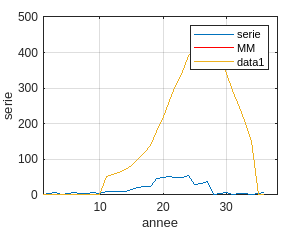

plot(x2,rolling_means(k-m:T-m),'r');
legend('serie','MM');
grid on;
plot(rolling_means)